# Hypothesis Testing: Argus II retinal prosthesis 

Sam Coleman

### Determine your question. State what you are trying to answer (e.g., what is the difference between values for category A and B, and is that difference meaningful?). 

It may be helpful to either sketch out or actually generate a plot to illustrate your question

We are primarily interested in understanding if the Argus II retinal prosthesis was effective in improving the subject's vision. The mean of the magnitude of difference between the target and the location of where the participant touched the screen. Each participant has the mean of 40 trials of the value for when the system is on and when the system is off. The data is continuous.

### Determine your null hypothesis, alternative hypothesis, alpha value

Null Hypothesis (H0): Argus II has no effect on people's vision. If the null hypothesis were true, the system being on (Argus II on) and the system being off (Argus II off) would not impact the means for each subject.

Alternative hypothesis: Argus II had an effect on people's vision (the mean of the magnitude of difference between the target and where the participant touched the screen is different for system on and system off)

Alpha value: .05 

### Conduct your experiment and collect your data.

Or in this case, load your data.

data = readtable("argusData.csv") %import data

data = 29×3 table
    Participant    SystemOn    SystemOff
    ___________    ________    _________

       {'A'}         128          372   
       {'B'}         115          319   
       {'C'}         177          324   
       {'D'}         106          343   
       {'E'}         121          385   
       {'F'}         201          382   
       {'G'}         178          300   
       {'H'}         190          181   
       {'I'}         122          347   
       {'J'}         120          386   
       {'K'}         112          209   
       {'L'}         211           -1   
       {'M'}         103          404   
       {'N'}         102          536   
       {'O'}         199          327   
       {'P'}         237          312   


### Organize and clean your data

Note how these data are organized (e.g, the values are in vector "values" and the categories are represented by the strings 'A' and 'B' in the vector "group"). Understand if these variables are categorical, discrete, continuous, counts, measurements, etc.

Plot the data to get a sense of what is there (boxplot, histogram, scatterplot, binned histogram, whatever makes sense)

Understand what each measurement represents, and if it is appropriate in its current form or if it needs to be transformed (e.g., change data to categorical, represent the information in a different form).

Make sure that the data are complete, or determine/justify what to do with incomplete data (e.g, remove points, estimate replacements).

### Understanding Data

Participants are represented by Strings 'A' to 'AC'. There is a mean of 40 trials for both the system on and system off for each participant. 

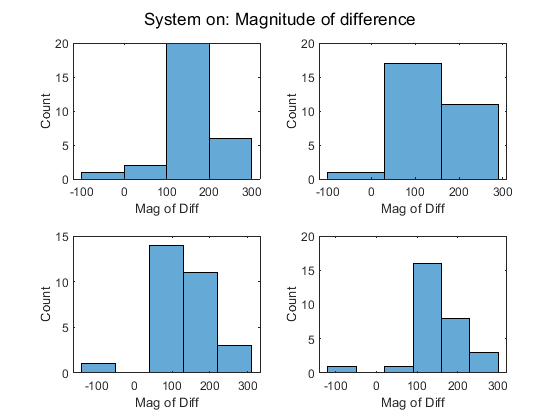

%Get an understanding of the distrubution
figure();
sgtitle("System on: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOn)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOn, 3)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOn, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOn, 6)
xlabel("Mag of Diff"); ylabel("Count");

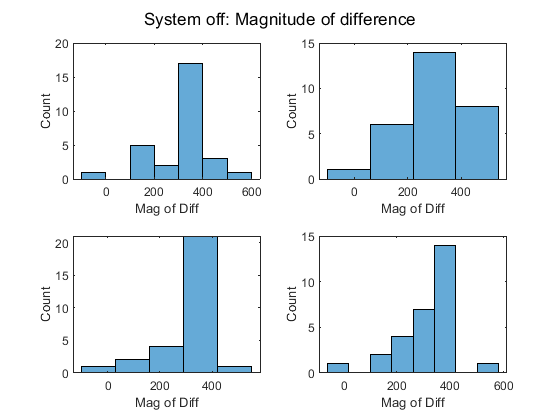


%Get an understanding of the distrubution
figure();
sgtitle("System off: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOff)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOff,4)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOff, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOff, 8)
xlabel("Mag of Diff"); ylabel("Count");

Looking at the histograms, we see there are negative values. This is not expected as the values are "the mean of the magnitude of difference." Below, I am looking closer into the negative values (based on the data I would expect everything to be >=0 but that is not the case).

%see (the number of and values of) negative data in both SystemOn and
%SystemOff
sum(data.SystemOn < 0) %1 negative SystemOn Val

ans = 1

data.SystemOn(data.SystemOn < 0) %val is -99

ans = -99


sum(data.SystemOff < 0) %1 negative SystemOff Val

ans = 1

data.SystemOff(data.SystemOff < 0) %val is -1

ans = -1

%look at the summary of the data
summary(data)


Variables:

    Participant: 29×1 cell array of character vectors

    SystemOn: 29×1 double

        Values:

            Min          -99    
            Median       128    
            Max          268    

    SystemOff: 29×1 double

        Values:

            Min            -1    
            Median        340    
            Max           536    



### Determine what types of tests/measurements are appropriate to answer your question. (You can actually do some of this ahead of time, but you’ll need to check the assumptions of the test to see if your data meet them.)

Consult resources like flow charts ([this](https://drive.google.com/file/d/11xmyMCgJBn8L9dcNGFVXXxOQiMbBfCfr/view?usp=sharing), [this](https://drive.google.com/file/d/1S5bUJG-uodKkRXI3-p7aWPG_QCzwQd4_/view), [this](https://drive.google.com/file/d/1xsNWHh7LPq6FdKQLuY8BWUMqLxcqdfUP/view), [this](https://drive.google.com/file/d/1K3rEKLTDYxIrHvHms07qxXkwcow180xr/view)), check out [this description of some common tests](https://drive.google.com/file/d/1ZE5eyqOPZL_I3WlW5pIk3_6No9K0uHEc/view?usp=sharing), or look online based on what you know about the types of variables and the type of question.

Consider the assumptions/constraints. When appropriate, test to make sure the assumptions are met (e.g., normality, or equal variances) or that the test is robust to violating the assumptions.

We have a set of data for each participant with using the Argus II and a set of data without using the Argus II. Therefore, I will use a paired sample T test. 

### Calculate appropriate measurements / tests (e.g., effect size, statistical significance, differences between means).

### Generate figure(s)/graph(s) to illustrate your findings.

### Summarize your findings in words, referring to your statistical tests and measurements.  (If you want to get fancy, you can look up APA style for reporting statistical tests.)